# GeigerCounterAudioAnalysis

*D. Carlsmith*

Examination of mobile phone audio recording of Geiger counter responding to radioactive sources and driving an audio speaker. Acoustic clicks are identified and counted to determine the mean count rate. Examines statistics of arrival times.

clear;

### Read in and examine audio files. 

Read a sample and plot the signal versus time.

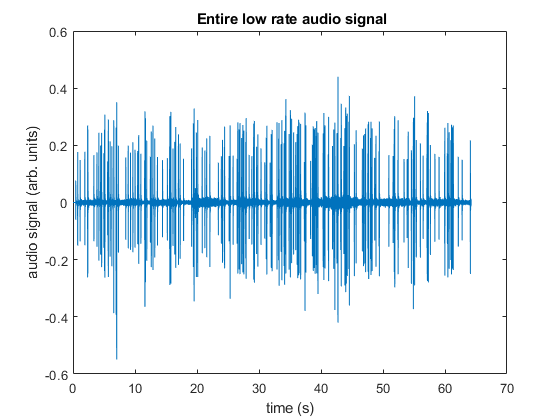

[ys,fs]=audioread('3sheets.m4a');
% y is the signal, fs the sample rate.
t=[1:length(ys)]/fs -1/fs;% times in s starting at 0
plot(t,ys); 
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Entire low rate audio signal')

There appears  60-cycle hum and pulses, each followed by room reverberation signals merging with each other.

Next, examine a high rate sample.

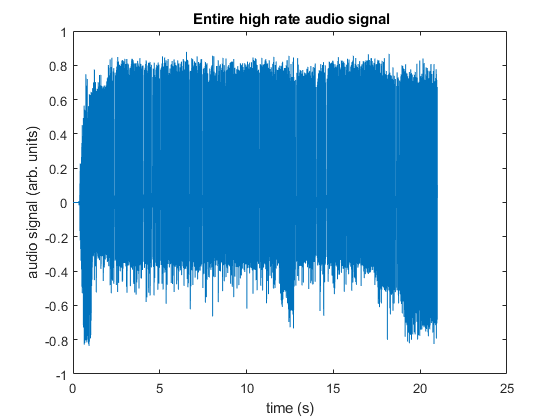

[y,fs]=audioread('just_source.m4a');
t=[1:length(y)]/fs -1/fs; % times in s starting at 0
plot(t,y);
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Entire high rate audio signal')

Create an audioplayer object to play the file

playerObj = audioplayer(y,fs);

Define by inspection start and ends times (in seconds) of valid range.

tstart = 5;tend=12; % find pulses

Compute corresponding sound data array indices and play the audio.

starttime = playerObj.SampleRate * tstart; % start play at tstart
endtime = playerObj.SampleRate * tend; % end play at tend
play(playerObj,[starttime,endtime]);

Define a valid range and a snippet range of data indices to zoom in  and plot the snippet signal to see pulses which last perhaps 5 ms.

Note: The snippet length should be chosen based on the pulse rate.

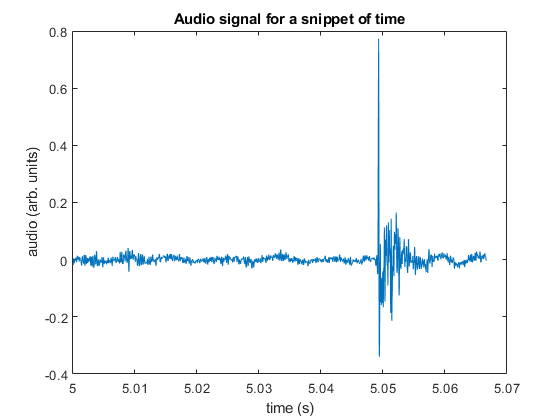

range0=t>tstart&t<tend;% define valid range (s)
range1=t>tstart&t<tstart+4*(1/60);% define a snippet (s)
plot(t(range1),y(range1));
xlabel('time (s)');ylabel('audio (arb. units)');
title('Audio signal for a snippet of time');

Use `findpeaks` to identify the pulses, using the snippet as a test. The algorithm searches for the highest peak within constraints designed to separate sparks, not the first peak in the spark signal, and plots the data indicating the peaks by default. (Open the figure in a separate window and zoom to explore how well it is working. Play with peak finding parameters to optimize. Change from range1 to range0 to peak-find over the whole valid range.)

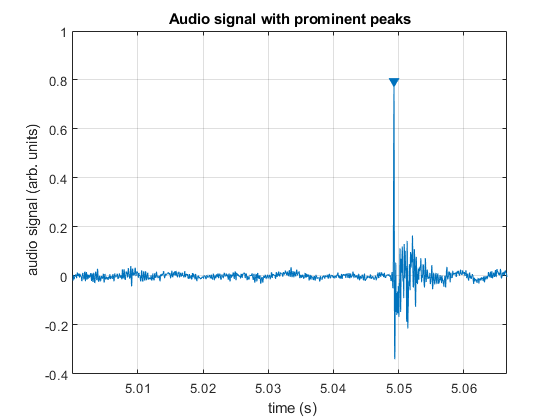

myThreshold = 0.01;
myMinPeakHeight = 0.2;
myMinPeakDistance = 0.0025;
findpeaks(y(range1),t(range1),'Threshold',myThreshold,...
    'MinPeakHeight',myMinPeakHeight,'MinPeakDistance',myMinPeakDistance)
xlabel(' time (s)');ylabel(' audio signal (arb. units)')
title('Audio signal with prominent peaks')

Apply the same selection to find peaks over the whole sample using range0. `findpeaks` returns locations (times where found peaks are located) when requested.

[pks,locs]=findpeaks(y(range0),t(range0),...
    'Threshold',myThreshold,...
    'MinPeakHeight',myMinPeakHeight,'MinPeakDistance',myMinPeakDistance);

And plot

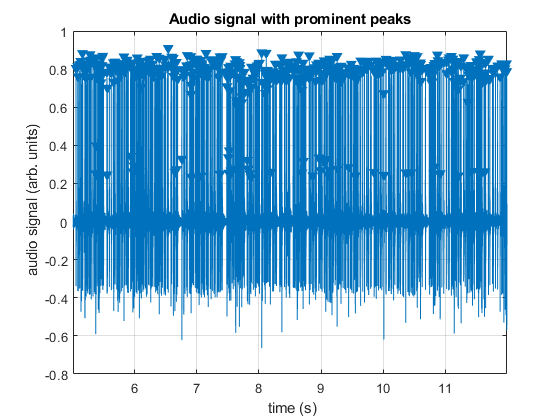

findpeaks(y(range0),t(range0),'Threshold',myThreshold,...
    'MinPeakHeight',myMinPeakHeight,'MinPeakDistance',myMinPeakDistance)
xlabel(' time (s)');ylabel(' audio signal (arb. units)')
title('Audio signal with prominent peaks')

### Count peaks and estimate mean rate and error.

npeaks = length(locs)

npeaks = 504

timerange = tend-tstart

timerange = 7

The probability of obtaining $N$ counts in time $T$ is for mean rate $R$ is $P(\bar N )=exp(-\bar N )(\bar N)^N/N!$ with $\bar N = RT$. The arguably best estimator for $R$ is $R=N/T$. The variance on the estimate of $\bar N$ equals $\bar N$ so the standard error on the rate can be estimated as $\sigma_R = \sqrt{N}/T$.

meanrate = npeaks/timerange

meanrate = 72

meanraterror = sqrt(npeaks)/timerange

meanraterror = 3.2071

### Analysis of time differences

The probability of an interval between decays is exponential with mean time $\tau=1/R$.

Get all the time differences `difflocs` between successive peaks and histogram them.

difflocs=diff(locs);
h=histogram(difflocs*1000, 11);
xlabel('time interval between pulses (ms)');
ylabel('counts');
%set(gca,'YScale','log');


meantimedifference= mean(difflocs);
ratefromdifferences = 1/meantimedifference;

weights = h.Values();
weights(weights==0) = 1;
weights = 1./weights;

vals = h.Values();
edges = h.BinEdges();
times = zeros(1,length(edges)-1);

for i = 1:(length(times))
    times(i) = (edges(i+1)+edges(i))/2;
end


modelfun = @(b,t)(b(1)+b(2)*exp(-t/b(3)));
b0=[1,vals(1),100]

b0 =      1   177   100


[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(times,vals,modelfun,b0, 'Weights', weights);

Print parameters and standard errors.

beta

beta =    -1.5378  238.7987   14.5874


err = sqrt(diag(CovB))

err =     1.2336
   16.2576
    1.0469


Note: We have not constrained the parameters. The constant term should be required to be positive if it represents background.

### Superpose fit on plot

thick=[times(1):length(times)/100:times(length(times))];
Predicted=modelfun(beta,thick)

Predicted =   188.2621  186.8362  185.4211  184.0165  182.6226  181.2391  179.8660  178.5032  177.1507  175.8083  174.4760  173.1537  171.8414  170.5389  169.2462  167.9632  166.6898  165.4260  164.1717  162.9268  161.6913  160.4651  159.2480  158.0402  156.8413  155.6515  154.4707  153.2987  152.1355  150.9810  149.8352  148.6981  147.5694  146.4493  145.3375  144.2341  143.1390  142.0522  140.9735  139.9029  138.8403  137.7857  136.7391  135.7003  134.6693  133.6461  132.6305  131.6226  130.6222  129.6294


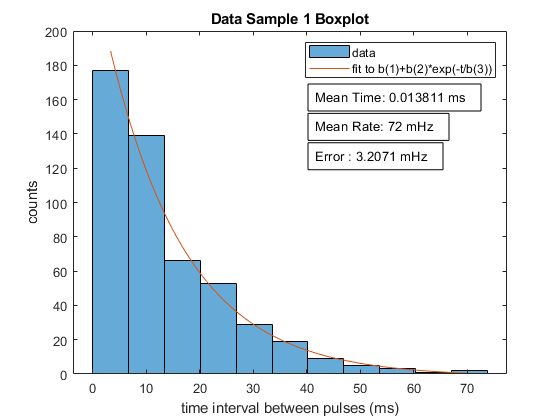

hold on
plot(thick,Predicted)
legend('data','fit to b(1)+b(2)*exp(-t/b(3))')
title('Data Sample 1 Boxplot')

dim = [.55 .5 1 .3];
str = 'Mean Time: ' + string(meantimedifference) + ' ms';
annotation('textbox',dim,'String',str,'FitBoxToText','on');

dim = [.55 .43 1 .3];
str = 'Mean Rate: ' + string(meanrate) + ' mHz';
annotation('textbox',dim,'String',str,'FitBoxToText','on');

dim = [.55 .36 1 .3];
str = 'Error : ' + string(meanraterror) + ' mHz';
annotation('textbox',dim,'String',str,'FitBoxToText','on');


hold off